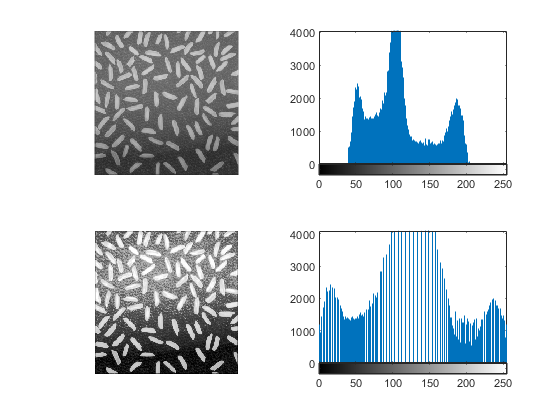

clc, clear, close all
I = imread('Fig2.tif');
subplot(2,2,1), imshow(I)
subplot(2,2,2), imhist(I)
if length(size(I)) == 2 % 判断I是否为灰度图像
    R = histeq(I, 256);
else
    I = rgb2gray(I); % 转灰度图像
    R = histeq(I, 256);
end
imwrite(R, 'histeq.tif')
subplot(2,2,3), imshow(R)
subplot(2,2,4), imhist(R)

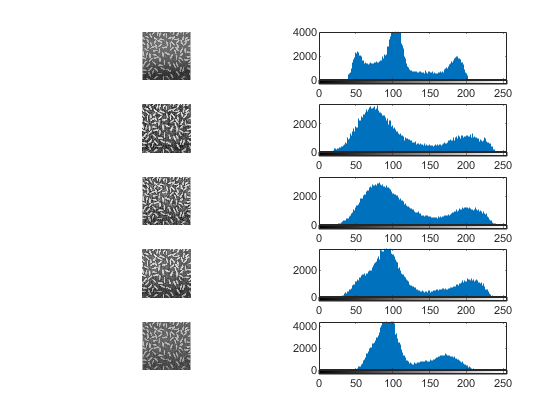

clc, clear, close all
I = imread('Fig2.tif');
subplot(5,2,1), imshow(I)
subplot(5,2,2), imhist(I)
if length(size(I)) == 2 % 判断I是否为灰度图像
    R1 = adapthisteq(I); % 默认自适应操作
    R2 = adapthisteq(I, 'NumTiles', [20,20]); % NumTiles 将图像分割成的矩形上下文区域（图块）的数量，指定为由正整数组成的二元素向量。
    R3 = adapthisteq(I, 'NumTiles', [20,20], 'ClipLimit',0.005); % ClipLimit 对比度增强限制，指定为 [0, 1] 范围内的数值。限值越高，对比度越大。
    R4 = adapthisteq(I, 'NumTiles', [20,20], 'ClipLimit',0.005, 'Distribution','rayleigh'); % 'rayleigh' 创建钟形直方图。
else
    I = mat2gray(I); % 转灰度图像
    R1 = adapthisteq(I);
    R2 = adapthisteq(I, 'NumTiles', [20,20]);
    R3 = adapthisteq(I, 'NumTiles', [20,20], 'ClipLimit',0.005);
    R4 = adapthisteq(I, 'NumTiles', [20,20], 'ClipLimit',0.005, 'Distribution','rayleigh');
end
imwrite(R1, 'adapthisteq1.tif')
imwrite(R2, 'adapthisteq2.tif')
imwrite(R3, 'adapthisteq3.tif')
imwrite(R4, 'adapthisteq4.tif')
subplot(5,2,3), imshow(R1)
subplot(5,2,4), imhist(R1)
subplot(5,2,5), imshow(R2)
subplot(5,2,6), imhist(R2)
subplot(5,2,7), imshow(R3)
subplot(5,2,8), imhist(R3)
subplot(5,2,9), imshow(R4)
subplot(5,2,10), imhist(R4)

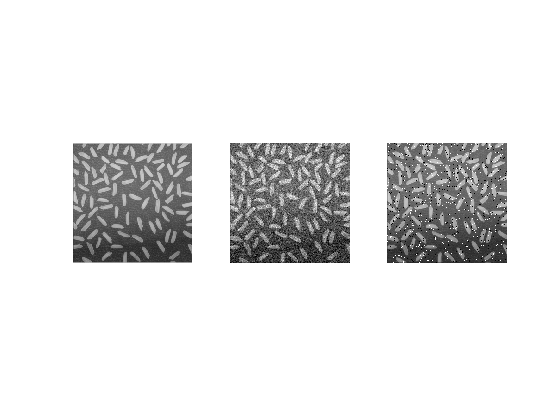

clc, clear, close all
I = imread('Fig2.tif');
R1 = imnoise(I,'gaussian'); % 加入高斯噪声，当然，还可以自定义很多参数
R2 = imnoise(I,'salt & pepper'); % 加入椒盐噪声，当然，还可以自定义很多参数
subplot(1,3,1), imshow(I)
subplot(1,3,2), imshow(R1)
subplot(1,3,3), imshow(R2)

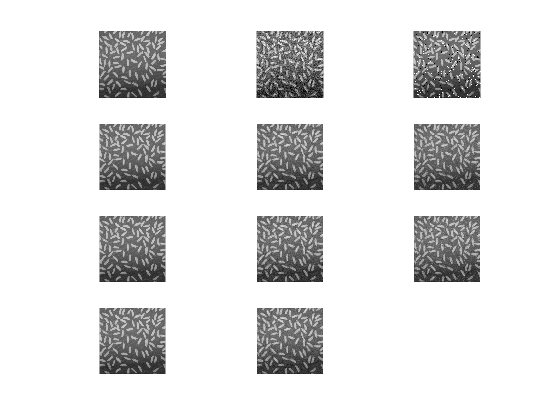

clc, clear, close all
I = imread('Fig2.tif');
R1 = imnoise(I,'gaussian'); % 加入高斯噪声，当然，还可以自定义很多参数
R2 = imnoise(I,'salt & pepper'); % 加入椒盐噪声，当然，还可以自定义很多参数
subplot(4,3,1), imshow(I)
subplot(4,3,2), imshow(R1)
subplot(4,3,3), imshow(R2)
subplot(4,3,4), imshow(I)
% 定义卷积模板
pattern1 = ones(3,3)*(1/9); % 最简单的3x3全1矩阵，领域平均法
pattern2 = ones(3,3); % 另一个如下所述的滤波器
pattern2(1,:) = [1,2,1];
pattern2(2,:) = [2,4,2];
pattern2(3,:) = [1,2,1];
pattern2 = pattern2*(1/16);
F1 = imfilter(R1,pattern1,'conv');
subplot(4,3,5), imshow(F1)
F2 = imfilter(R2,pattern1,'conv');
subplot(4,3,6), imshow(F2)
subplot(4,3,7), imshow(I)
F3 = imfilter(R1,pattern2,'conv');
subplot(4,3,8), imshow(F3)
F4 = imfilter(R2,pattern2,'conv');
subplot(4,3,9), imshow(F4)
pattern3 = ones(3,3); % 另一个如下所述的滤波器
pattern3(1,:) = [1,1,1];
pattern3(2,:) = [1,0,1];
pattern3(3,:) = [1,1,1];
pattern3 = pattern3*(1/8);
subplot(4,3,10), imshow(I)
F5 = imfilter(R1,pattern3,'conv');
subplot(4,3,11), imshow(F5)
F6 = imfilter(R2,pattern3,'conv');
subplot(4,3,12), imshow(F6)

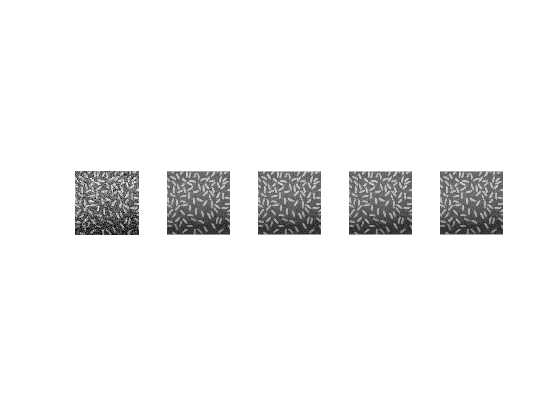

close all
H = fspecial('average'); % 平均值滤波器
filteredZero = imfilter(R1, H, 0); % 无填充
filteredSymmetric = imfilter(R1, H, 'symmetric'); % symmetric
filteredReplicate = imfilter(R1, H, 'replicate'); % replicate
filteredCircular = imfilter(R1, H, 'circular'); % circular
subplot(1,5,1), imshow(R1)
subplot(1,5,2), imshow(filteredZero)
subplot(1,5,3), imshow(filteredSymmetric)
subplot(1,5,4), imshow(filteredReplicate)
subplot(1,5,5), imshow(filteredCircular)

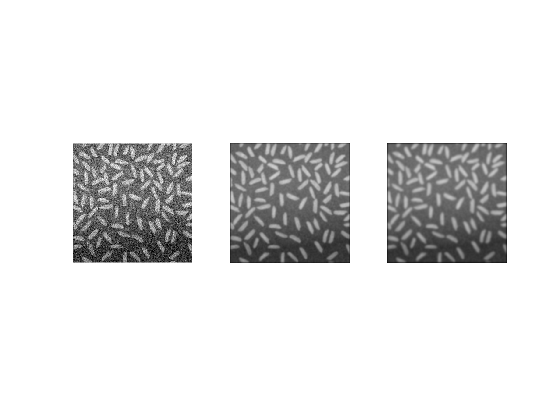

close all
H = fspecial('average'); % 平均值滤波器
filteredZero = imfilter(R1, H, 0); % 无填充
for i = 0:9 % 循环10次
    if i == 0
        filteredZero10 = imfilter(filteredZero, H, 0); % 无填充
    else
        filteredZero10 = imfilter(filteredZero10, H, 0); % 无填充
    end
end
for i = 0:20 % 循环20次
    if i == 0
        filteredZero20 = imfilter(filteredZero, H, 0); % 无填充
    else
        filteredZero20 = imfilter(filteredZero20, H, 0); % 无填充
    end
end
subplot(1,3,1), imshow(R1)
subplot(1,3,2), imshow(filteredZero10)
subplot(1,3,3), imshow(filteredZero20)